%%Vehicle/Enivronment Parameters
Vehicle

ans =   Vehicle with properties:

             Mass: []
    friction_coef: []
       Area_front: []
        drag_coef: []
     wheel_radius: []
       gear_ratio: []
            delta: []
       efficiency: []



a = Vehicle;

%vehicle
a.Mass                  = 1000;                     %Mass           [kg]
a.friction_coef         = 0.03;                     %friction coefficient
a.gear_ratio            = 3;                        %gear ratio
a.wheel_radius          = 0.3;                      %wheel radius   [m]
a.Area_front            = 1.5;                      %frontal area   [m^2]
a.delta                 = 1+0.04+0.0025*i_g^2;      %rotational inertia factor
a.efficiency            = 0.95;                     %efficiency
a.drag_coef             = 0.2;                      %drag coefficient




%Environment
alpha   = 0;                        %inclination    [degrees]
V_kph   = 100;                      %Vehicle speed  [km/h]
V_ms    = V_kph/3.6;                %Vehicle speed  [m/s]
V_w_kph = 0;                        %Wind speed     [km/h]
V_w_ms  = V_w_kph *(1000/3600);     %Wind speed     [m/s]




%Calculation for maximum speed on a flat surface;

%tractive force for maximum speed
F_maxspeed = tractive_force(0,300,V_w_ms,a); 

%torque required for max speed
T_maxspeed = (F_maxspeed*r_w)/(a.gear_ratio*a.efficiency);


%Torque function test
v = linspace(0,300,n)

v =          0    0.6012    1.2024    1.8036    2.4048    3.0060    3.6072    4.2084    4.8096    5.4108    6.0120    6.6132    7.2144    7.8156    8.4168    9.0180    9.6192   10.2204   10.8216   11.4228   12.0240   12.6253   13.2265   13.8277   14.4289   15.0301   15.6313   16.2325   16.8337   17.4349   18.0361   18.6373   19.2385   19.8397   20.4409   21.0421   21.6433   22.2445   22.8457   23.4469   24.0481   24.6493   25.2505   25.8517   26.4529   27.0541   27.6553   28.2565   28.8577   29.4589


T = arrayfun(@(V) Torque(V,20e3,350e3,a), v)

T = 1.0e+03 *

    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872    1.8872


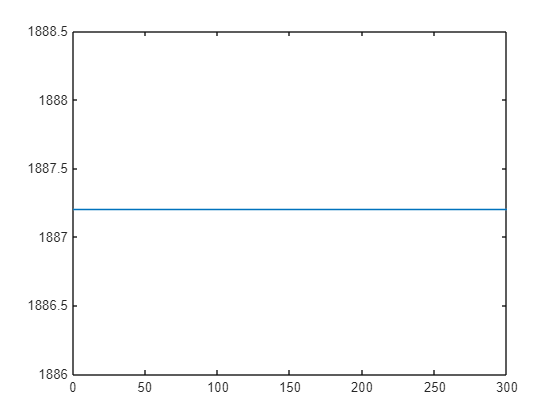

plot(v,T)

%Define function to integrate
func = @(v) a.Mass * a.delta ./ (Torque(v,20e3,350e3,a)*a.gear_ratio*a.efficiency/a.wheel_radius - tractive_force(0,v,0,a));

%integrate
t = integral(func,0,100)

t = 6.0424

function [F_r] = tractive_force(alpha,V_kph,V_w_ms,a) 



%Physical constants
g       = 9.81;                     %Gravity        [m/s^2]
rho     = 1.293;                    %density of air [kg/m^3]

%Vehicle speed in m/s
V_ms = V_kph./3.6; 

%Friction force 
F_f = a.Mass * g * a.friction_coef * cosd(alpha);          

%Gradeability force
F_g = a.Mass * g * sind(alpha);              

%Drag force
F_w = 0.5 * rho * a.Area_front * a.drag_coef * (V_ms-V_w_ms).^2; 

%Total tractive effort at a steady state
F_r = F_f + F_g + F_w; 

end

%Geting that torque curve
function [T] = Torque(V_kph, Tmax, Pmax, a)

%traction coefficient
mu_p = 0.9;


V_ms = V_kph./3.6;

w = V_ms./(a.wheel_radius * a.gear_ratio);


Fn = 9.81*(a.Mass/4); %No downforce
Ftmax = Fn * mu_p;
Twtmax = Ftmax * a.wheel_radius;
Tptmax = Twtmax * a.gear_ratio*a.efficiency;

T = min([Pmax./w,Tmax,Tptmax]);

end

%code that didnt really fit


% %Calculation for maximum gradeability;
% 
% F_maxgrade = tractive_force(10,100,M,g,f_r,rho,A_f,C_d,V_w_ms); 
% T_maxgrade = (F_maxgrade*r_w)/(i_g*n_d);
